# Taller de Simulación Numérica

*F. Pena, P. Quintela*

## Tema 1. El método de diferencias finitas. Condición de contorno Dirichlet

Consideramos el siguiente problema de contorno $(P_D)$ con condiciones de contorno Dirichlet:


$$\left\{\begin{array}{ll}y''(x) = F(x,y,y'),\\y(a)=y_a,\\y(b) = y_b.\end{array}$$


## Teorema de existencia y unicidad de solución

Consideramos $F(x,y,z)$ definida en $R=[a,b]\times\mathbb{R}\times\mathbb{R}$. Si se verifica que:

- $F$, $\partial_x F$, $\partial_y F$ y $\partial_{z} F$ son continuas en $R$,

- $\partial_y F > 0$ en $R$,

- existe $M$ tal que $|\partial_{z} F| < M
$en $R$,

entonces el problema (P_D) admite una única solución en $[a,b]$ (véase [H.B. Keller. Existence theory for two point boundary value problems. Bull. Amer. Math. Soc. 72(4):728-731. 1966](https://projecteuclid.org/journals/bulletin-of-the-american-mathematical-society-new-series/volume-72/issue-4/Existence-theory-for-two-point-boundary-value-problems/bams/1183528184.full)).

## Aproximación numérica de la solución

Tomamos una partición regular $[a,b]$ en *n* intervalos, siendo 

- el *parámetro (o paso) de discretización* $h = \frac{b-a}{n}$,

- los *puntos de la discretización *$x_i = a+i h$ para $i\in\{0,\ldots,n\}$. 

La solución aproximada en $x_i$ se denotará por $y_i$. Usaremos las siguientes fórmulas de aproximación de la derivada:


$$y'(x_i) = \frac{y(x_{i+1})-y(x_{i-1})}{2h}+O(h^2)$$



$$y''(x_i) = \frac{y(x_{i+1})-2y(x_i)+y(x_{i-1})}{h^2}+O(h^2)$$


Usándolas en (P_D) obtenemos el problema discretizado:


$$\left\{\begin{array}{l}y_0=y_a,\\
\frac{y_{i+1}-2y_i+y_{i-1}}{h^2}=F\left(x_i,\  y_i,\  \frac{y_{i+1}-y_{i-1}}{2h}\right),\ i=1,\ldots, n-1,\\
y_n=y_b\,.\end{array}\right.$$


En esta práctica trabajaremos con una ecuación diferencial ordinaria (EDO) lineal.

## Caso lineal

Tomamos $F(x,y, y') = u(x) + v(x)y+w(x)y'$. El problema lineal discretizado $(P_{DLh})$ es:


$$\left\{\begin{array}{l}y_0=y_a\\
a_i\,y_{i-1}+ d_i\, y_i+c_i\,y_{i+1}=-h^2u_i,\ i=1,\ldots, n-1\\
y_n=y_b\end{array}\right.$$


con $u_i = u(x_i),\ v_i = v(x_i),\ w_i = w(x_i)$ y

 
$$


\begin{array}{rcrcl}
a_i &=& -1&-&\frac{h}{2}w_i\,, \\
d_i &=& 2 &+&h^2v_i\,, \\ 
c_i &=& -1&+&\frac{h}{2}w_i\,.
\end{array}$$


Es decir, es un sistema tridiagonal:


$$\left(\begin{array}{cccc}
d_1 & c_1 &  &  & 0 \\
a_2 & d_2 & c_2 & &  \\
  & a_3 & d_3 & \!\!\!\!c_3 &\\
& &  \!\!\!\!\!\!\!\!\!\!\!\ddots & \!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\ddots &\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\ddots \\
  &  & a_{n-2}  & d_{n-2}  & c_{n-2}  \\
0 &  &   & a_{n-1}  & d_{n-1} \\
\end{array} \right) \left(\begin{array}{c}y_1\\y_2\\y_3\\ \vdots\\y_{n-2}\\y_{n-1}\end{array}\right) = 
 \left(\begin{array}{l}-h^2u_1-a_1\,y_a\\-h^2u_2\\-h^2u_3\\ \qquad \vdots\\-h^2u_{n-2}\\-h^2u_{n-1}-c_{n-1}\,y_b\end{array}\right)$$


## Buen planteamiento del problema discreto

La matriz del sistema tridiagonal es estrictamente diagonal dominante si $|a_i|+|c_i|<|d_i|$. 

Como $|d_i|>2$, basta pedir que $\left|\frac h2 w_i\right|<1$para que $|a_i| + |c_i| = |1+\frac{h}{2}w_i| + |1-\frac{h}{2}w_i| = 2<|d_i|$.

En la práctica, basta tomar $h < \frac 2M_w$, con $M_w = \max_{x\in[a,b]}|w(x)|$.

Además, si el problema lineal discretizado verifica:

- $u$, $v$, $w$ continuas en $[a,b]$, $v>0$ en $[a,b]$,

entonces $\max_{0\leq i\leq n}|y(x_i)-y_i| = O(h^2)$, siendo $y(x)$ e $\{y_i\}_{i=0}^n$ las soluciones de (P_D) y (P_{DLh}), respectivamente. 

## Implementación del método de diferencias finitas

La función [`dfd`](http://dfd.m) implementa el cálculo de la solución del problema (P_{DLh}). Sus argumentos de entrada son:

- La estructura `F,` con tres funciones anónimas `u`, `v` y `w` que admiten como argumento un vector `x` de puntos de discretización.

- La estructura `bc,` con los extremos del intervalo, `a`, `b`, y el valor de la solución en los extremos, `ya`, y`b`.

- El número de pasos, `n`.

El resultado es:

- El vector de puntos de discretización, `x`, 

- El vector de valores de la solución aproximada en los puntos anteriores, `y`. 

**Atención:** En las explicaciones anteriores, algunos índices empiezan en cero (por ejemplo, los puntos de discretización $\{x_i\}_{i=0}^n$). Sin embargo, en Matlab los índices deben empezar en uno.

## Ejercicio 1.1. Test académico

Considera el problema de contorno:


$$\left\{\begin{array}{ll}y''(x) = 2\text{e}^x-y,\\y(0)=2,\\y(1) = \text{e}+\cos(1).\end{array}$$


- **Calcula la solución del problema discretizado mediante diferencias finitas con 25 pasos.**

Una estructura, `foo`, con dos campos: un escalar, `foo.a,` y una función anónima, `foo.b`, se puede definir como:

%foo = struct( 'a', 2.54, ...
%              'b', @(t) ones(size(t)) );
%con esta estructura a cada cosa que le pongo entre comillas liego puedo llamarla haciendo foo.(lo que quiera)

Define a continuación los argumentos de entrada de [dfd](http://dfd.m) y llama a la función para que devuelva `[xh,yh]`.

%Solucion
F=struct('u',@(x) 2*exp(x),'v',@(x)-ones(size(x)),'w',@(x) zeros(size(x)));
bc=struct('a',0,'b',1,'ya',2,'yb',exp(1)+cos(1));
[xh,yh]=dfd(F,bc,25)

xh =          0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000


yh =     2.0000    2.0400    2.0801    2.1203    2.1608    2.2015    2.2426    2.2842    2.3264    2.3693    2.4129    2.4575    2.5031    2.5499    2.5980    2.6475    2.6986    2.7515    2.8063    2.8631    2.9223    2.9839    3.0481    3.1151    3.1852    3.2586


- **Calcula la solución exacta del usando **[`dsolve`](https://es.mathworks.com/help/symbolic/dsolve.html)**.**

Se recomienda llamar a [`dsolve`](https://es.mathworks.com/help/symbolic/dsolve.html) con argumentos simbólicos. El resultado se transformará a un *manejador de función* ([function handle](https://es.mathworks.com/help/matlab/function-handles.html)) (función anónima) mediante [matlabFunction](https://es.mathworks.com/help/symbolic/matlabfunction.html), para acelerar su evaluación. Por ejemplo:

%syms y(x)
%foo = matlabFunction(dsolve(diff(y,x,2) == x+y, [y(0)==0, y(1)==3]));

Calcula la solución exacta, `sol`, y obtén su evaluación en los puntos de discretización, y`e`.

%Solucion
% definimos una función simbólica que depende de x en términos simbólicos
syms y(x)
sysol=dsolve(diff(y,x,2)+y==2*exp(x),[y(bc.a)==bc.ya, y(bc.b)==bc.yb ])%como tengo dos condiciones de conrtonto las doy en un array

$$sysol = \cos\left(x\right)+{\mathrm{e}}^{x}\,\sin\left(x\right)\,\left(\cos\left(x\right)+\sin\left(x\right)\right)+{\mathrm{e}}^{x}\,\cos\left(x\right)\,\left(\cos\left(x\right)-\sin\left(x\right)\right)-\frac{\sin\left(x\right)\,\left(2251799813685248\,\cos\left(1\right)+2251799813685248\,{\cos\left(1\right)}^{2}\,\mathrm{e}+2251799813685248\,\mathrm{e}\,{\sin\left(1\right)}^{2}-7337679146555661\right)}{2251799813685248\,\sin\left(1\right)}$$

sol=matlabFunction(sysol)

sol = function_handle with value:
    @(x)cos(x)+exp(x).*sin(x).*(cos(x)+sin(x))+exp(x).*cos(x).*(cos(x)-sin(x))-(sin(x).*(cos(1.0).*2.251799813685248e+15+cos(1.0).^2.*exp(1.0).*2.251799813685248e+15+exp(1.0).*sin(1.0).^2.*2.251799813685248e+15-7.337679146555661e+15))./(sin(1.0).*2.251799813685248e+15)


- **Calcula la norma **$L^{\infty}(a,b)$ **discreta del error, tanto absoluto como relativo.**

La norma $L^{\infty}(a,b)$ discreta de $\{y_i\}_{i=0}^n$ se calcula como $\|y\|_{\infty} = \max_{0\leq i\leq n}|y(x_i)|$. Consulta la ayuda del comando [`norm`](https://es.mathworks.com/help/matlab/ref/norm.html).

Al calcular eI error relativo debe utilizarse [`eps`](https://es.mathworks.com/help/matlab/ref/eps.html) en aquellas componentes del denominador próximas a cero.

%Solucion
% comenzamos con la solución exacta
ye=sol(xh)

ye =     2.0000    2.0400    2.0801    2.1203    2.1607    2.2015    2.2426    2.2842    2.3264    2.3692    2.4129    2.4575    2.5031    2.5498    2.5979    2.6475    2.6986    2.7515    2.8062    2.8631    2.9222    2.9838    3.0481    3.1151    3.1852    3.2586


% podemos comenzar calculando el error abosluto
err=abs(ye-yh)

err = 	1.0e+-4 *

         0    0.0669    0.1293    0.1870    0.2400    0.2879    0.3307    0.3682    0.4002    0.4266    0.4473    0.4621    0.4709    0.4736    0.4702    0.4604    0.4443    0.4217    0.3925    0.3567    0.3143    0.2651    0.2091    0.1463    0.0766         0


norm(err,'inf')%ponemos inf para cakcular la norma infinito

ans = 4.7364e-05

% es costumbre poner esto bonito empleando un display
disp(['La norma infintio del error absokuto es ',num2str(norm(err,'inf'))]) %le pasamos un array de cadenas que queremos que nos concatene

La norma infintio del error absokuto es 4.7364e-05


disp(['La norma infintio del error relativo es ',num2str(norm(err./max(abs(ye),eps),'inf'))])%tenemos que sumar el epsilon al dividir para evitar un error catastrófico si tuvieramos soluciones muy próximas a cero 

La norma infintio del error relativo es 1.8813e-05


%notemos que lo que queremos calcular es esencialmengte ||ye-yh||/||ye||

- **Representa grá**`fi`**camente la solución exacta, la aproximada y el error cometido en cada punto.**

Utiliza [errorbar](https://es.mathworks.com/help/matlab/ref/errorbar.html) para mostrar el error y magnifica su valor por $10^4$ para observarlo claramente. 

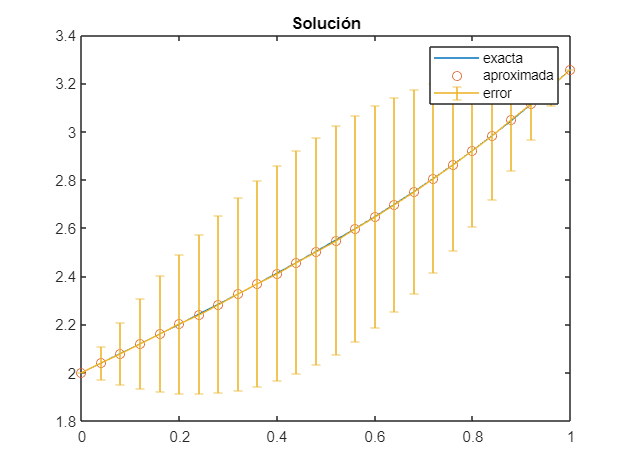

%Solucion
plot(xh,ye,xh,yh,'o');hold on
escala=1e4;%ponemos la escala para poder ver los errores
errorbar(xh,ye,escala*err);hold off 
legend('exacta','aproximada','error')
title('Solución')

- **Comprueba que el error se reduce al reducirse el paso de discretización.**

%Solucion
[xh,yh]=dfd(F,bc,250);
ye=sol(xh);
err=abs(ye-yh);%calculamos el nuevo error absoluto
disp(['La norma infintio del error absokuto es ',num2str(norm(err,'inf'))])

La norma infintio del error absokuto es 4.7358e-07


disp(['La norma infintio del error relativo es ',num2str(norm(err./max(abs(ye),eps),'inf'))])

La norma infintio del error relativo es 1.8837e-07


- **Deduce numéricamente el orden del método para la solución aproximada.**

Si la solución es de orden exactamente $p$, tomando dos parámetros de discretización $h_1$ y $h_2$ suficientemente pequeños, entonces los errores correspondientes $e_1$ y $e_2$ verifican:

$\frac{e_1}{e_2}\approx\left(\frac{h_1}{h_2}\right)^p$, es decir, $p\approx\frac{\log(e_1/e_2)}{\log(h_1/h_2)}$*.*

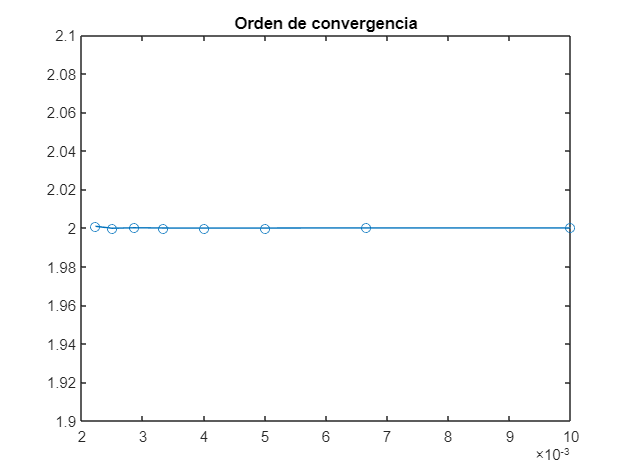

%Solucion
n=100:50:500;
h=(bc.b-bc.a)./n;
err=zeros(size(n));
for i=1:length(n)
    [xh,yh]=dfd(F,bc,n(i));
    err(i)=norm(yh-sol(xh),'inf');%erro absoluto en norma infinito
end
p=log(err(2:end)./err(1:end-1))./log(h(2:end)./h(1:end-1));
plot(h(1:end-1),p,'o-');
axis([h(end) h(1) 1.9 2.1 ])
title('Orden de convergencia')

- **Deduce numéricamente el orden del método para la derivada de la solución aproximada.**

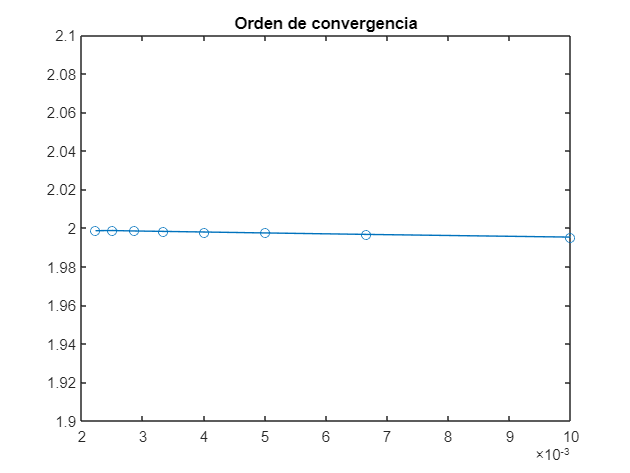

%Solucion
%calcuylamos la derivada de la solucióin numérica en los puntos intermedios
%empleando una fórmula de derivación numérica
n=100:50:500;
h=(bc.b-bc.a)./n;
d1=@(y,h) (y(3:end)-y(1:end-2))/(2*h);%tener cuidado con los índices
dsol=matlabFunction(diff(sysol));%derivada exacta  de la solución excata
err=zeros(size(n));
for i=1:length(n)
    [xh,yh]=dfd(F,bc,n(i));
    dyh=d1(yh,h(i));
    err(i)=norm(dyh-dsol(xh(2:end-1)),'inf');%erro absoluto en norma infinito
end
p=log(err(2:end)./err(1:end-1))./log(h(2:end)./h(1:end-1));
plot(h(1:end-1),p,'o-');
axis([h(end) h(1) 1.9 2.1 ])
title('Orden de convergencia')

## Coordenadas esféricas

Considera el cambio a coordenadas esféricas $(r, \theta, \varphi)\in[0,+\infty)\times[0,2\pi)\times[0,\pi]$:


$$\left\{\begin{array}{l}
x = r\cos\theta\sin\varphi,\\
y = r\sin\theta\sin\varphi,\\
z = r\cos\varphi.
\end{array}$$


Inversamente,


$$r = \sqrt{x^2+y^2+z^2}$$



$$\theta = \left\{\begin{array}{ll}
\arctan\left(\frac{y}{x}\right) &\text{si }  x>0,y>0,\\
\arctan\left(\frac{y}{x}\right)+2\pi &\text{si }  x>0,y<0,\\
\frac{\pi}{2}\text{sign}\,(y) &\text{si }  x=0,\\
\arctan\left(\frac{y}{x}\right)+\pi &\text{si }  x<0.
\end{array}\right.$$



$$\varphi = \left\{\begin{array}{ll}
\arctan\left(\frac{\sqrt{x^2+y^2}}{z}\right) & \text{si }  z>0,\\
\pi/2                                                          & \text{si }  z=0,\\
\arctan\left(\frac{\sqrt{x^2+y^2}}{z}\right)+\pi & \text{si }  z<0.\\
\end{array}\right.$$


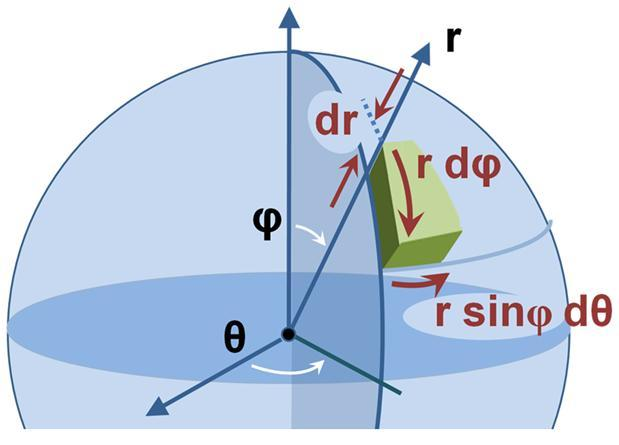

[Brews ohare, CC BY-SA 3.0](https://commons.wikimedia.org/wiki/File:Volume_element_spherical_coordinates.JPG)

Dado un campo escalar $\phi$ y un vectorial $\mathbf{F}$, su gradiente y divergencia en coordenadas esféricas son:


$$\nabla\phi(x,y,z) = \partial_r\phi\,\mathbf{e}_r+\frac{1}{r}\partial_{\theta} \phi\,\mathbf{e}_{\theta}+\frac{1}{r\sin\theta}\partial_\varphi\theta\,\mathbf{e}_{\varphi}$$



$$\nabla\cdot\mathbf{F}(x,y,z) = \frac{1}{r^2}\partial_{r}(r^2\mathbf{F}_r)+
\frac{1}{r\sin\theta}\partial_{\theta}(\sin(\theta)\mathbf{F}_{\theta})+
\frac{1}{r\sin\theta}\partial_{\varphi}\mathbf{F}_{\varphi}$$


## Ejercicio 1.2. Planteamiento del problema térmico con simetría esférica

Considera la ecuación del calor estacionaria en el dominio dado por la corona esférica de radio $r,\ r_i\leq r\leq r_e$ siendo un medio homogéneo con conductividad térmica $k$ constante, con temperatura constante dada en el exterior y fuente de calor $f$:


$$\left\{\begin{array}{l}
-\nabla\cdot(k\nabla T(x,y,z)) = f(x,y,z),\\
T = T_i \qquad \text{si }  x^2+y^2+z^2= r_i^2, \\
T = T_e \qquad \text{si }  x^2+y^2+z^2= r_e^2.\end{array}\right.$$


- **Estudia el problema anterior con una fuente de calor que solo dependa de **$r$**.**

Demuestra que, en estas condiciones, $T(r)$ verifica el problema unidimensional (P1.2):


$$\left\{\begin{array}{l}
-\frac{1}{r^2}\frac{\mathrm{d}}{\mathrm{d}r}\left(kr^2\frac{\mathrm{d}T(r)}{\mathrm{d}r}\right)  = f(r),\\
T(r_i) = T_i, \\
T(r_e) = T_e.
\end{array}\right.
$$


Solución:

## Ejercicio 1.3. Resolución del problema térmico con simetría esférica

Considera el problema (P1.2) con fuente de calor nula y datos $r_i=1\, \mathrm{m},\ r_e=2\, \mathrm{m},\ 
T_i=0\, \text{ºC},\ 
T_e=100\, \text{ºC}
 $.

- **Calcula la solución aproximada mediante diferencias finitas.** 

Solución:

%Solucion

- **Representa la solución en un corte ecuatorial de la corona esférica.** 

Para representar un campo escalar definido sobre un dominio plano, se recomienda usar [meshgrid](https://es.mathworks.com/help/matlab/ref/meshgrid.html) para particionar el dominio y usar [surf](https://es.mathworks.com/help/matlab/ref/surf.html) o [mesh](https://es.mathworks.com/help/matlab/ref/mesh.html) para la representación gráfica, o [contour](https://es.mathworks.com/help/matlab/ref/contour.html) o [contourf](https://es.mathworks.com/help/matlab/ref/contourf.html) para los conjuntos de nivel. Por ejemplo:

%[X,Y] = meshgrid(1:0.5:10, 1:20);
%Z = sin(X) + cos(Y);
%surf(X,Y,Z)

En el caso de que el dominio esté descrito con otro tipo de coordenadas, la partición debe calcularse en dichas coordenadas. Por ejemplo:

%[R,Th] = meshgrid(5:0.1:10, 0:pi/100:2*pi);
%X = R.*cos(Th); Y = R.*sin(Th);
%Z = -R.^2;
%contourf(X,Y,Z)

En nuestro caso, la solución unidimensional debe repetirse con [repmat](https://es.mathworks.com/help/matlab/ref/repmat.html) para cada valor de $\theta$ para obtener la matriz de valores en $z$:

%x = 1:0.1:2; y = x.^2;
%Z = repmat(y, length(x), 1)

Usa las ideas anteriores para representar `yh` en un corte ecuatorial de la corona esférica:

%Solucion

- **Calcula la solución exacta del usando **[`dsolve`](https://es.mathworks.com/help/symbolic/dsolve.html)**.**

Calcula la solución exacta, `sol`, y obtén su evaluación en los puntos de discretización, y`e`:

%Solucion

- **Calcula la norma **$L^{\infty}(r_i,r_e)$**discreta del error absoluto.**

%Solucion

- **Calcula la norma **$L^2(r_i, r_e)$ **discreta del error absoluto.**

Una observación sobre normas en espacios continuos y discretos: dada una partición $\{x_i\}_{i=0}^n$ de $[a,b]$, podemos asociar a una función $y(x)$ definida en $[a,b]$ su discretización $\mathbf{y} = \{y(x_i)\}_{i=0}^n$. Si$y\in L^\infty(a,b)$ entonces $\|y\|_{L^\infty(a,b)} = \max_{x\in[a,b]}|y(x)|<+\infty$ y podemos denominar *norma *$L^\infty$* discreta de *$y$ a la norma $\|\mathbf{y}\|_{\infty} = \max_{0\leq i \leq n}|y(x_i)|$. Esta definición es natural pues $\lim_{n\to \infty} \|\mathbf{y}\|_{\infty} = \|y\|_{L^\infty(a,b)}$.

Ahora, si consideramos una función $y\in L^2(a,b)$ con norma $\|y\|_{L^2(a,b)} = \left(\int_a^by(x)^2\,\mathrm{d}x\right)^\frac{1}{2}$, ya no es adecuado denominar norma $L^2$ discreta de $y$ a la norma 2 de su discretización,  $\|\mathbf{y}\|_2 = 
 \left(\sum_{i=0}^ny(x_i)^2\right)^\frac{1}{2}$, pues el límite de esta ya no es la norma $L^2$. Por contra, denominamos *norma *$L^2$* discreta de *$y$ a la norma $L^2(a,b)$ donde la integral se aproxima numéricamente usando la discretización $\mathbf{y}$. Podemos usar el comando [trapz](https://es.mathworks.com/help/matlab/ref/trapz.html) para integrar la discretización mediante la regla de trapecios  compuesta. 

%Solucion

- **Calcula la norma **$L^2(C)$ **discreta del error absoluto, siendo **$C$ **la corona esférica.**

Considera el [cambio de variable a esféricas en la integral triple](https://math.libretexts.org/Bookshelves/Calculus/Map%3A_Calculus__Early_Transcendentals_(Stewart)/15%3A_Multiple_Integrals/15.08%3A_Triple_Integrals_in_Spherical_Coordinates) que define la norma,

$\int_C e^2\, \mathrm{d}v = \left(\int_0^{\pi}\int_0^{2\pi}\int_{r_i}^{r_e} e^2(r)\, r^2\sin\varphi\,\mathrm{d}r\,\mathrm{d}\theta\,\mathrm{d}\varphi\right)^{\frac{1}{2}}$* . *

Como $e = e(r)$y $\int_0^{\pi}\sin\varphi\,\mathrm{d}\varphi = 2$ entonces $\int_C e^2\, \mathrm{d}v = \left(4\pi\int_{r_i}^{r_e} e^2(r)\, r^2\,\mathrm{d}r\right)^{\frac{1}{2}}$. Usa el comando [trapz](https://es.mathworks.com/help/matlab/ref/trapz.html) para integrar mediante la regla de trapecios el error discreto. 

%Solucion